# Exercice 2:

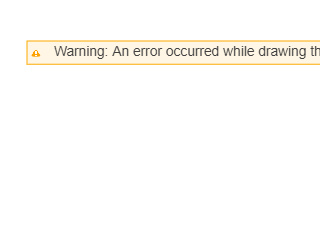

clear all
close all
figure;i2=imread('foggysf2.jpg');
title('Image_Initiale');
subplot(221)
imshow(i2) ; 
g=rgb2gray(i2);
subplot(222)
imshow(g);
subplot(223)
imhist(g);
b=imbinarize(g,"global");
title("L'histogramme de l'image en niveau de gris")
subplot(224)
imshow(b);

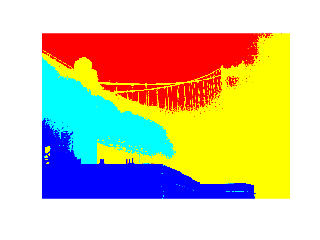

s=multithresh(g,3);
q=imquantize(g,s);
seg=label2rgb(q);
figure;
imshow(seg)

figure;
for n=6:20
s=multithresh(g,n);
q=imquantize(g,s);
seg=label2rgb(q);

subplot(3,5,n-5),
imshow(seg),
end

## Exercice3:

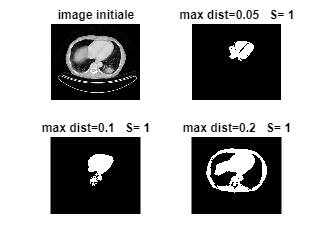

clear all
figure;
i3=imread('medtest.png');
subplot(221);imshow(i3);title("image initiale")

c=im2double(i3);

x=120;y=260 ;
j1=regiongrowing(c,x,y,0.05);
s1=surfacee(j1);
subplot(222);
imshow(j1)
title("max dist=0.05   S= "+s1);
j2=regiongrowing(c,x,y,0.1);
s2=surfacee(j2);
subplot(223);
imshow(j2)
title("max dist=0.1   S= "+s2)
j3=regiongrowing(c,x,y,0.2);
s3=surfacee(j3);
subplot(224);
imshow(j3)
title("max dist=0.2   S= "+s3)

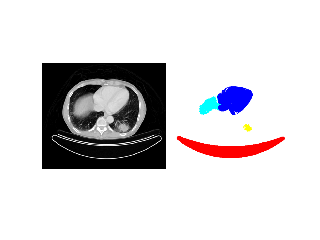

js=zeros(size(c)); 
G=[120 260;160 160;248 310;340 240];
for i=1:size(G,1)
x=G(i,1);y=G(i,2);
j=regiongrowing(c,x,y,0.07);
js=js+j*i;
s(i)=surfacee(j);
end
res=label2rgb(js);
figure;
montage({c,res});

disp("surface de region");

surface de region


disp(s');

     1
     1
     1
     1



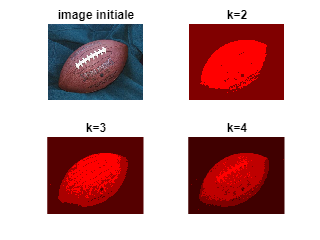


clear all 
figure; 
i4=imread('football.jpg'); 
subplot(221);imshow(i4);title("image initiale") 

[mu1,mask1]=kmeans(i4,2);
mask1=mat2gray(mask1);
subplot(222);imshow(mask1);title("k=2") 

[mu2,mask2]=kmeans(i4,3);
mask2=mat2gray(mask2);
subplot(223);imshow(mask2);title("k=3") ;

[mu3,mask3]=kmeans(i4,4);
mask3=mat2gray(mask3);
subplot(224);imshow(mask3);title("k=4")

function s=surfacee(I)
s=bwarea(i);
end